# **Build the Deep-Learning Model**

Load the spectrogram images as an image datastore.The [`imageDatastore`](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html) function automatically labels the images based on folder names and  stores the data as an ImageDatastore object. An image datastore enables  you to store large image data, including data that does not fit in  memory, and efficiently read batches of images during training of a CNN. 

allImages = imageDatastore(fullfile("G:\Document_G\PUMP\Label_data"),...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');

% Train Test split. train 80%, test 20%
rng default
[imgsTrain,imgsValidation] = splitEachLabel(allImages,0.8,'randomized');
fprintf(['Number of training images: %d\n'...
    'Number of validation images: %d\n'],numel(imgsTrain.Files), numel(imgsValidation.Files));

Number of training images: 256
Number of validation images: 64


# **GoogLeNET**

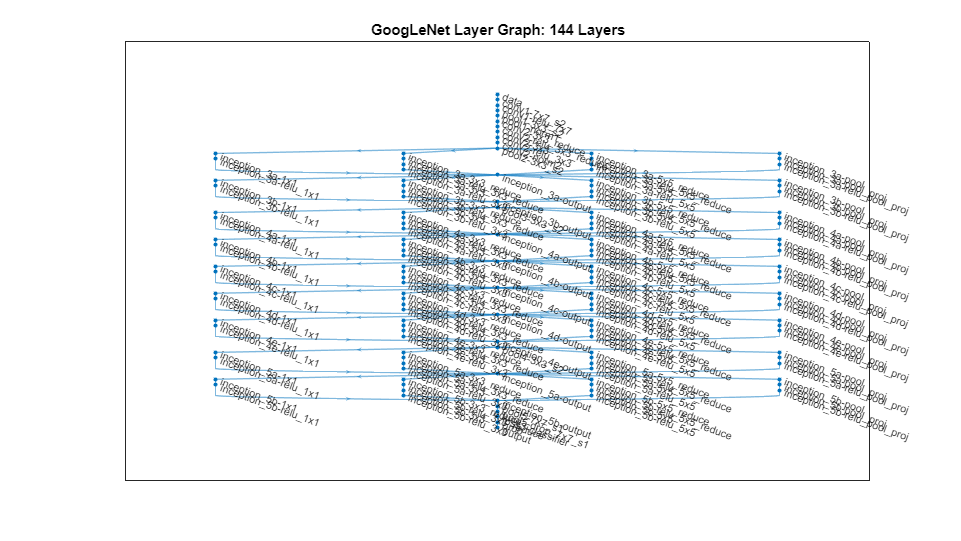

% Load the pretrained GoogLeNet neural network.
net = googlenet;
% Extract and display the layer graph from the network.
lgraph = layerGraph(net);
numberOfLayers = numel(lgraph.Layers);
figure('Units','normalized','Position',[0.1 0.1 0.8 0.8]);
plot(lgraph)
title(['GoogLeNet Layer Graph: ',num2str(numberOfLayers),' Layers']);

net.Layers(1) % inspect the first element of the network Layers property.

ans =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [224 224 3]

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


% retrain GoogLeNet for our pressure pump classification problem.
% Add new dropout layer
newDropoutLayer = dropoutLayer(0.6,'Name','new_Dropout');
lgraph = replaceLayer(lgraph,'pool5-drop_7x7_s1',newDropoutLayer);

% Replace the fully connected layer 'loss3-classifier' with a new fully
% connected layer with the number of filters equal to the number of classes.
numClasses = numel(categories(imgsTrain.Labels));
newConnectedLayer = fullyConnectedLayer(numClasses,'Name','new_fc',...
    'WeightLearnRateFactor',5,'BiasLearnRateFactor',5);
lgraph = replaceLayer(lgraph,'loss3-classifier',newConnectedLayer);

% Replace the classification layer with a new one without class labels.
% trainNetwork automatically sets the output classes of the layer at training time.
newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'output',newClassLayer);

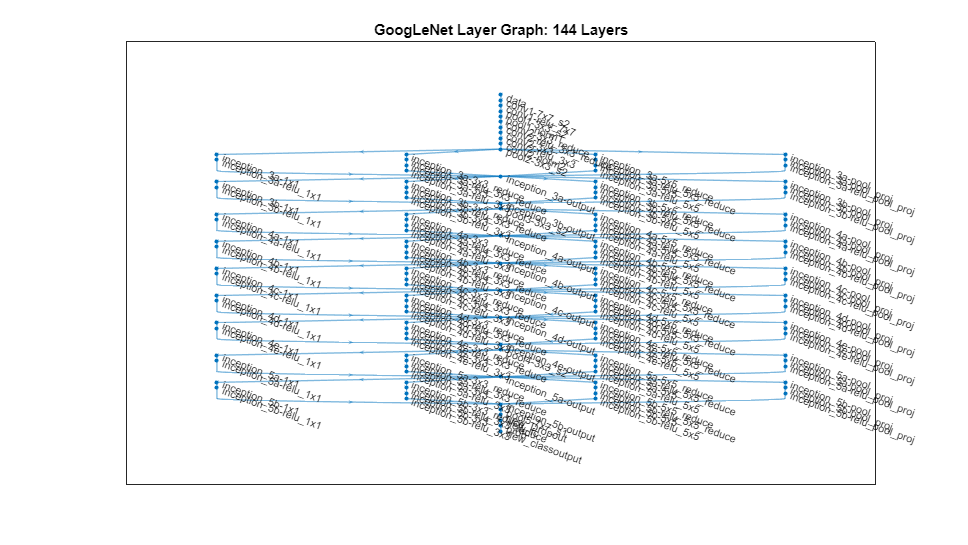

% inspect the new layer we replaced.
numberOfLayers = numel(lgraph.Layers);
figure('Units','normalized','Position',[0.1 0.1 0.8 0.8]);
plot(lgraph)
title(['GoogLeNet Layer Graph: ',num2str(numberOfLayers),' Layers']);

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:06 |       60.00% |       50.00% |       1.1479 |       1.0710 |      1.0000e-04 |
|       1 |          10 |       00:00:23 |       73.33% |       82.81% |       0.4213 |       0.4260 |      1.0000e-04 |
|       2 |          20 |       00:00:39 |      100.00% |       82.81% |       0.1407 |       0.3319 |      1.0000e-04 |
|       2 |          30 |       00:00:56 |       80.00% |       84.38% |       0.4496 |       0.3223 |      1.0000

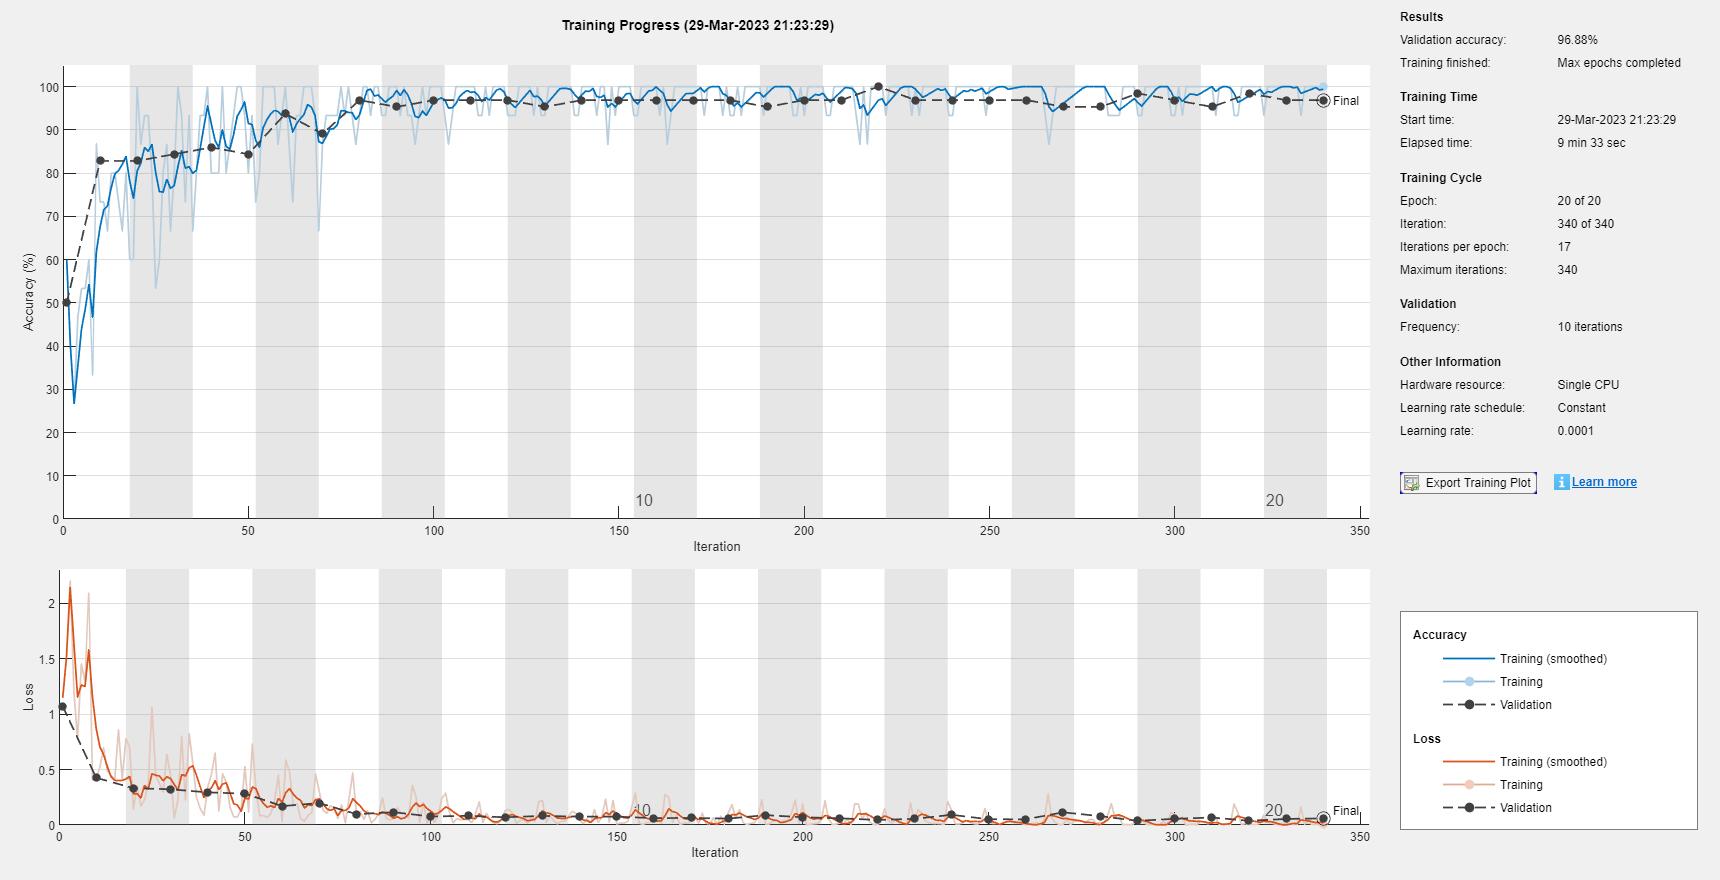

% Set Training Options and Train GoogLeNet
options = trainingOptions('sgdm',...
    'MiniBatchSize',15,...
    'MaxEpochs',20,...
    'InitialLearnRate',1e-4,...
    'ValidationData',imgsValidation,...
    'ValidationFrequency',10,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');
rng default

trainedGN = trainNetwork(imgsTrain,lgraph,options); % Model

trainedGN.Layers(end);

## **Model Evaluation**

% Model Accuracy
[YPred,probs] = classify(trainedGN,imgsValidation);
accuracy = mean(YPred==imgsValidation.Labels);
disp(['GoogLeNet Accuracy: ',num2str(100*accuracy),'%']);

GoogLeNet Accuracy: 96.875%


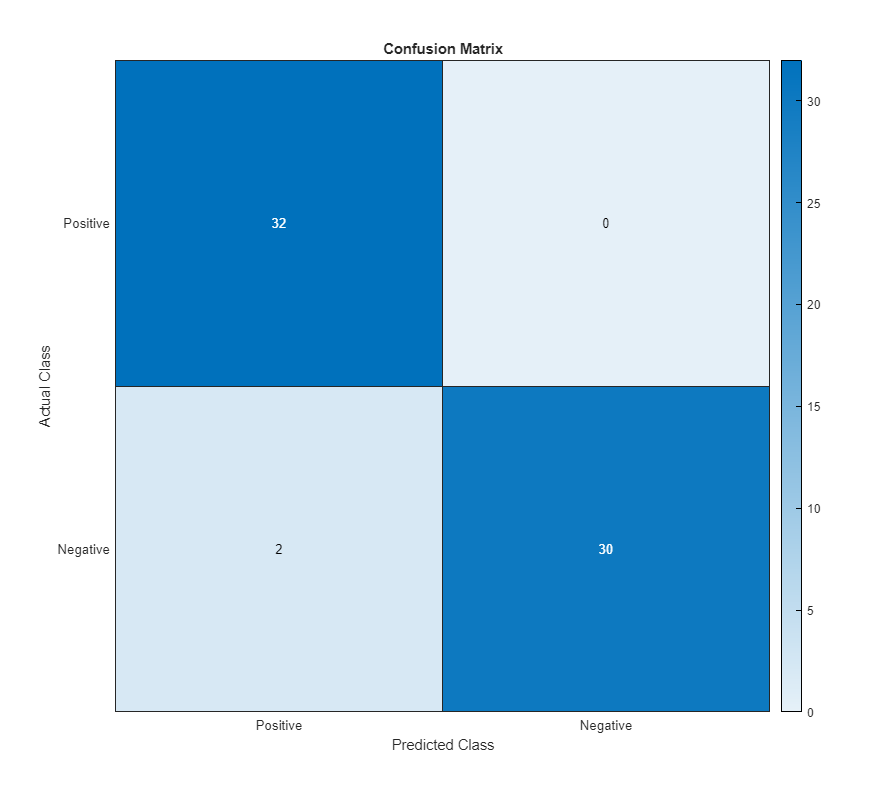

% Confusion Matrix
[C,~] = confusionmat(imgsValidation.Labels, YPred,'Order',{'Abnormal','Normal'});
h = heatmap({'Positive','Negative'}, {'Positive','Negative'}, C);
h.Title = 'Confusion Matrix';
h.XLabel = 'Predicted Class';
h.YLabel = 'Actual Class';

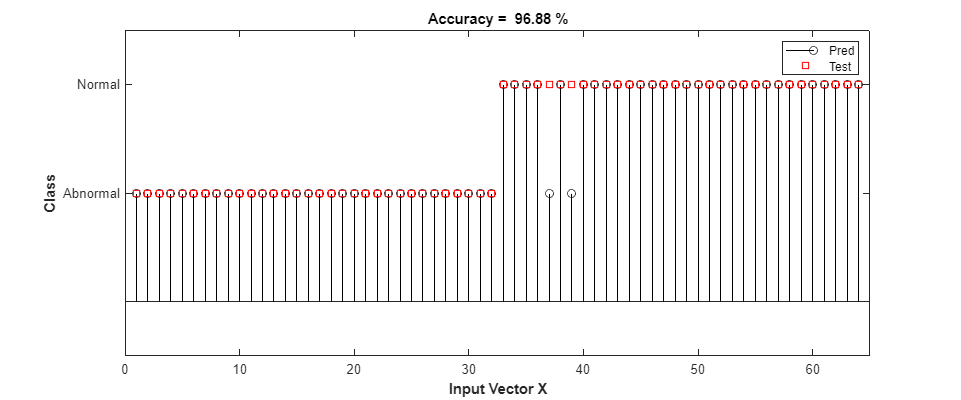

% Lolipop Chart
f1 = figure;
f1.Position(3:4) = [1200,500];
s = stem(YPred,...
     'Color',"black");
t = sprintf("Accuracy =  %.2f %c", (100*accuracy),'%');
title(t)
xlabel("Input Vector X","FontWeight","bold");
ylabel("Class","FontWeight","bold");
xlim([0,65]);
hold on
dot = scatter(1:1:numel(imgsValidation.Labels),imgsValidation.Labels,[],"red","square","LineWidth",1);
legend({'Pred','Test'}); 
hold off

## **Explore GoogLeNet Activations**

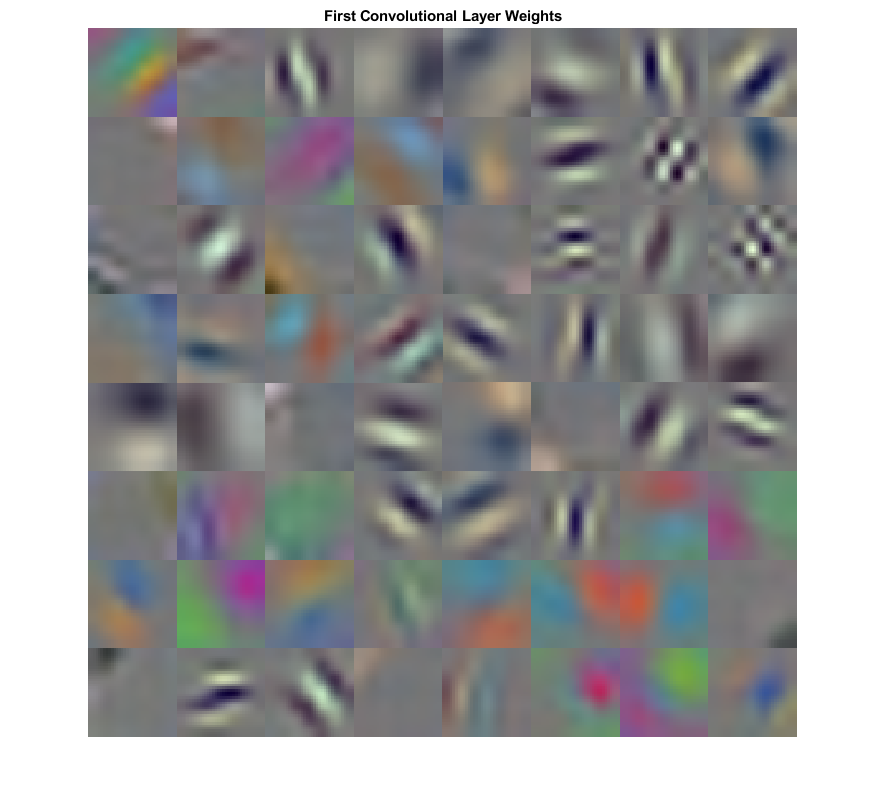

wghts = trainedGN.Layers(2).Weights;
wghts = rescale(wghts);
wghts = imresize(wghts,5);
figure
montage(wghts)
title('First Convolutional Layer Weights')

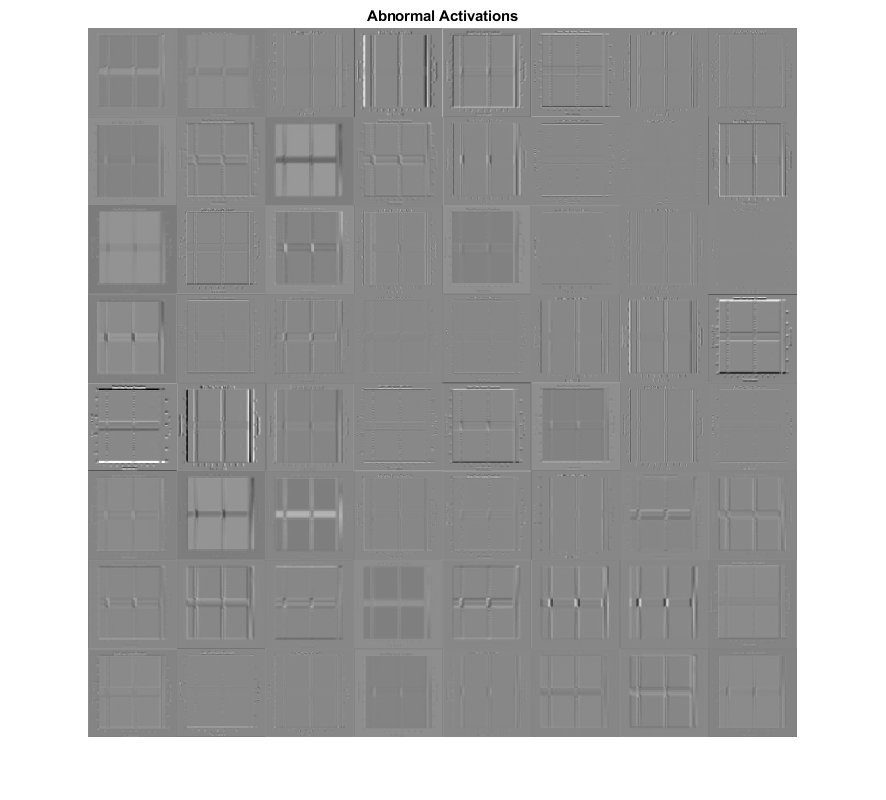

% Examine which areas in the convolutional layers activate on an image from the Abnormal class.
convLayer = 'conv1-7x7_s2';
imgClass = 'Abnormal';
imgName = 'Abnormal10.jpg';
imgExample = ["Abnormal118.jpg", "Normal100.jpg"];
imarr = imread(fullfile("G:\Document_G\PUMP\Label_data",imgClass,imgName));

trainingFeaturesAbnormal = activations(trainedGN,imarr,convLayer);
sz = size(trainingFeaturesAbnormal);
% reshape to 4d array (wigth, heigth, color, channel)
trainingFeaturesAbnormal = reshape(trainingFeaturesAbnormal,[sz(1), sz(2), 1, sz(3)]);
figure
montage(rescale(trainingFeaturesAbnormal),'Size',[8 8])
title([imgClass,' Activations'])

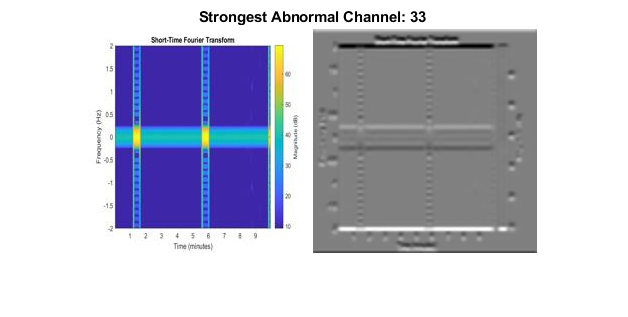

% Find the strongest channel for this image. Compare the strongest channel with the original image.
imgSize = size(imarr);
imgSize = imgSize(1:2);
[~,maxValueIndex] = max(max(max(trainingFeaturesAbnormal)));
abMax = trainingFeaturesAbnormal(:,:,:,maxValueIndex);
abMax = rescale(abMax);
abMax = imresize(abMax,imgSize);
figure;
imshowpair(imarr,abMax,'montage')
title(['Strongest ',imgClass,' Channel: ',num2str(maxValueIndex)])

analyzeNetwork(net);

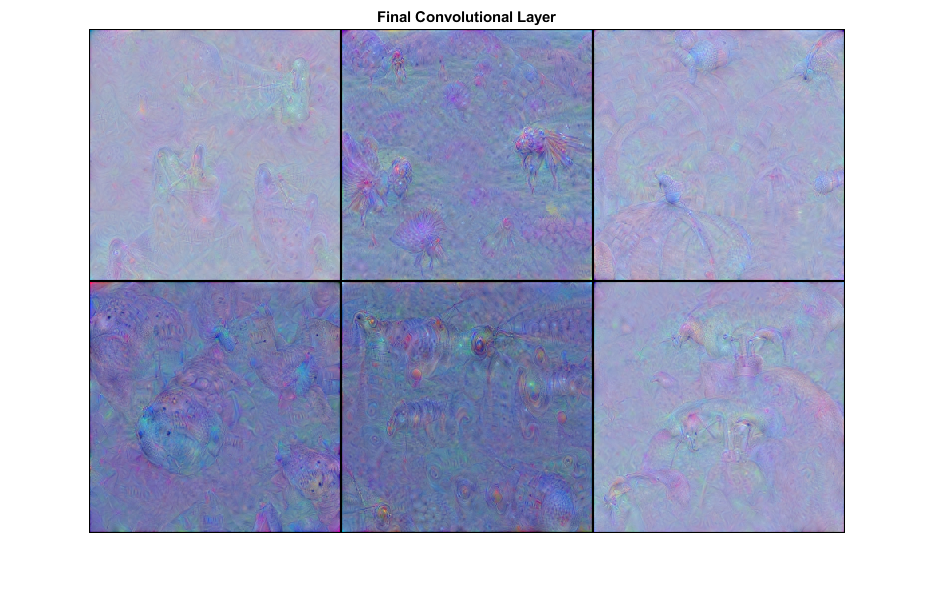

% Inspect what features the layer have learned.
convLayer1 = "inception_5b-pool_proj";
subfolder = ["Abnormal", "Normal"];
channels = [4,8,16,32,64,128];
I = deepDreamImage(trainedGN,convLayer1, channels, ...
        'Verbose',false, ...
        'NumIterations',20, ...
        'PyramidLevels',2);
I = imtile(I,'ThumbnailSize',[250 250],'BorderSize',[1,1]);
imshow(I)
title("Final Convolutional Layer")

# **SqueezNet**

sqz = squeezenet;

lgraphSqz = layerGraph(sqz);
disp(['Number of Layers: ',num2str(numel(lgraphSqz.Layers))])

Number of Layers: 68


disp(lgraphSqz.Layers(1).InputSize)

   227   227     3



lgraphSqz.Layers(end-5:end) % Inspect the last six layers

ans =   6×1 Layer array with layers:

     1   'drop9'                             Dropout                      50% dropout
     2   'conv10'                            Convolution                  1000 1×1×512 convolutions with stride [1  1] and padding [0  0  0  0]
     3   'relu_conv10'                       ReLU                         ReLU
     4   'pool10'                            2-D Global Average Pooling   2-D global average pooling
     5   'prob'                              Softmax                      softmax
     6   'ClassificationLayer_predictions'   Classification Output        crossentropyex with 'tench' and 999 other classes

% Replaced dropout layer with new one.
newDropoutLayer = dropoutLayer(0.6, 'Name', "new_dropout");
lgraphSqz = replaceLayer(lgraphSqz, "drop9", newDropoutLayer);

% Replaced convolutional layer with new one.
numClasses = numel(categories(imgsTrain.Labels));
newLearnableLayer = convolution2dLayer(1, numClasses, ...
    "Name","new_conv", ...
    "WeightLearnRateFactor",10, ...
    "BiasLearnRateFactor",10);
lgraphSqz = replaceLayer(lgraphSqz, "conv10", newLearnableLayer);

% Replace convolutional layer with new one.
newClassLayer = classificationLayer("Name","new_classoutput");
lgraphSqz = replaceLayer(lgraphSqz, lgraphSqz.Layers(end).Name, newClassLayer);

% inspect new layer we replaced.
lgraphSqz.Layers(63:68)

ans =   6×1 Layer array with layers:

     1   'new_dropout'       Dropout                      60% dropout
     2   'new_conv'          Convolution                  2 1×1 convolutions with stride [1  1] and padding [0  0  0  0]
     3   'relu_conv10'       ReLU                         ReLU
     4   'pool10'            2-D Global Average Pooling   2-D global average pooling
     5   'prob'              Softmax                      softmax
     6   'new_classoutput'   Classification Output        crossentropyex

analyzeNetwork(sqz)

% Resize image in image datastore to compatible with SqeezNet.
augimgsTrain = augmentedImageDatastore([227 227],imgsTrain);
augimgsValidation = augmentedImageDatastore([227 227],imgsValidation);

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |       60.00% |       67.19% |       1.0859 |       0.6858 |          0.0003 |
|       1 |          25 |       00:00:17 |       80.00% |       93.75% |       0.4363 |       0.1271 |          0.0003 |
|       2 |          50 |       00:00:29 |       90.00% |       93.75% |       0.1510 |       0.1919 |          0.0003 |
|       3 |          75 |       00:00:41 |       90.00% |       96.88% |       0.2664 |       0.0606 |          0.

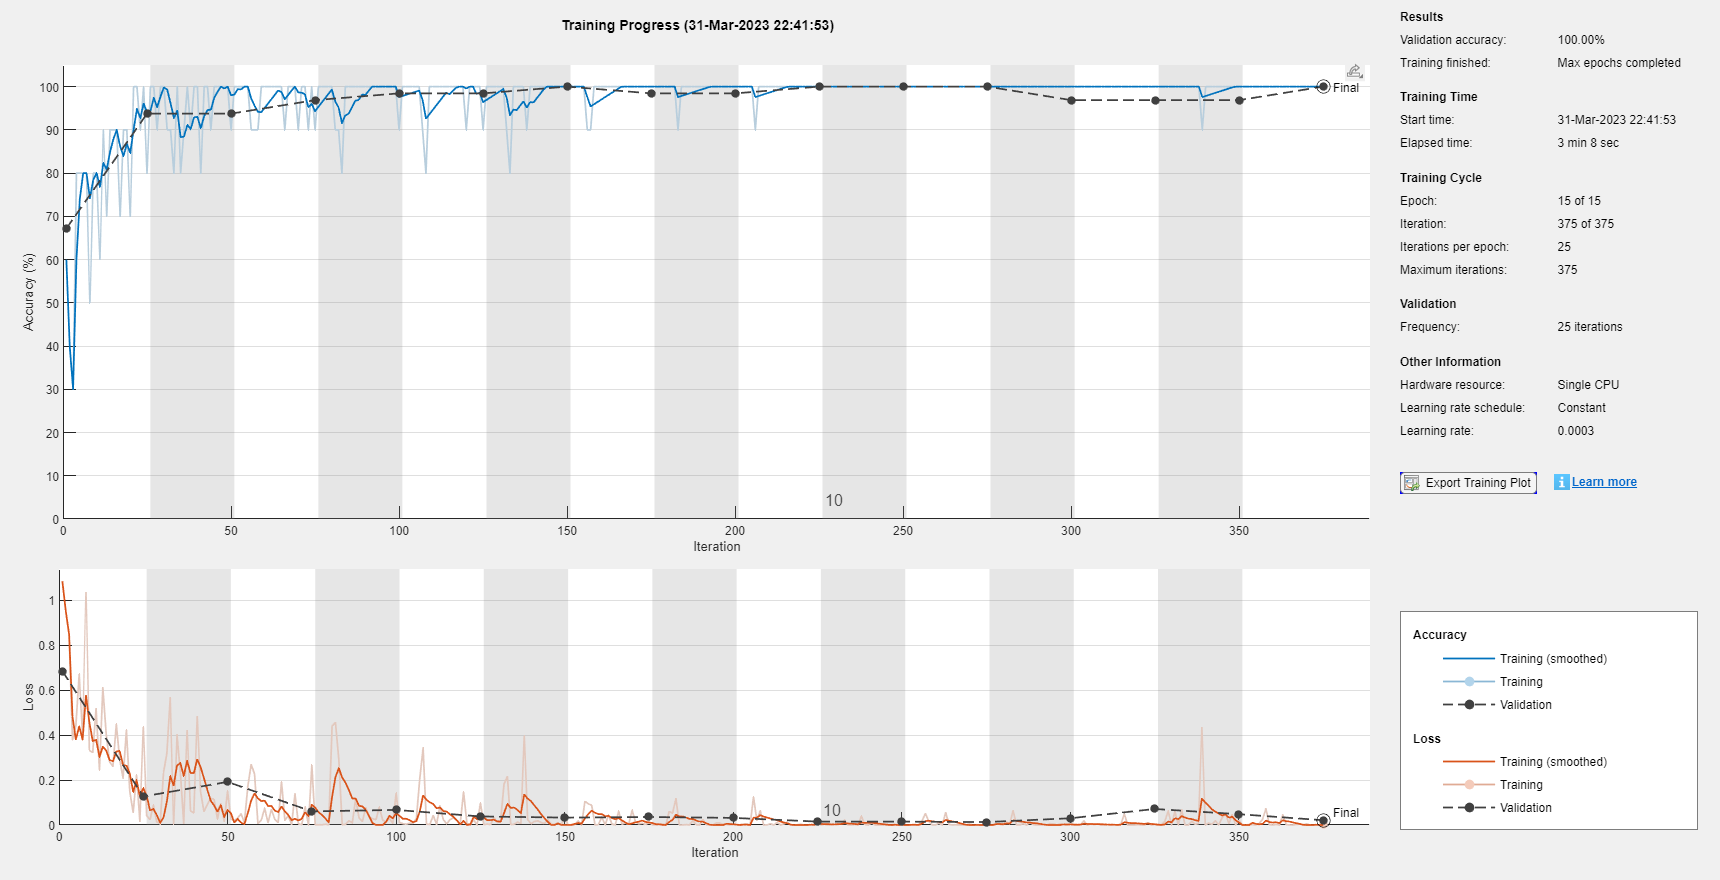

% Set tainning option and train model.
ilr = 3e-4; % initial learning rate
miniBatchSize = 10; 
maxEpochs = 15;
valFreq = floor(numel(augimgsTrain.Files)/miniBatchSize); % 256/10 = 25.6 -> 25 (floor)
opts = trainingOptions('sgdm',...
    'MiniBatchSize',miniBatchSize,...
    'MaxEpochs',maxEpochs,...
    'InitialLearnRate',ilr,...
    'ValidationData',augimgsValidation,...
    'ValidationFrequency',valFreq,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');

rng default
trainedSN = trainNetwork(augimgsTrain,lgraphSqz,opts);

## **Model Evaluation**

[YPred,prob] = classify(trainedSN,augimgsValidation);
accuracy = mean(YPred==imgsValidation.Labels);
disp(['SqueezeNet Accuracy: ',num2str(100*accuracy),'%'])

SqueezeNet Accuracy: 100%


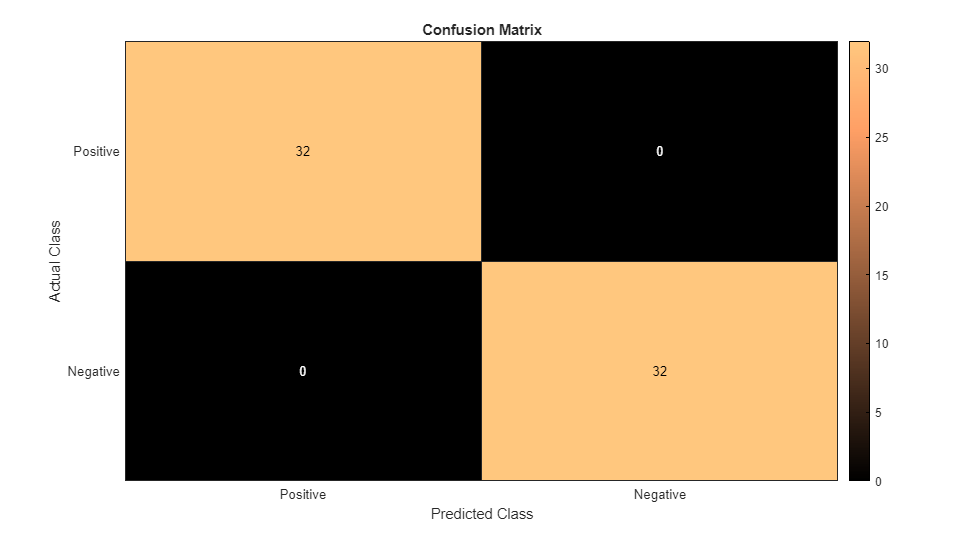

[C,order] = confusionmat(imgsValidation.Labels, YPred,'Order',{'Abnormal','Normal'});
h = heatmap({'Positive','Negative'}, {'Positive','Negative'}, C, "Colormap", copper);
h.Title = 'Confusion Matrix';
h.XLabel = 'Predicted Class';
h.YLabel = 'Actual Class';